% Prova Kalman Filter 

% Modello senza noise
% x[n + 1] = Ax[n] + Bu[n]
%     y[n] = Cx[n] 

% Modello con noise
% x[n + 1] = Ax[n] + Bu[n] + Gw[n]
%     y[n] = Cx[n] + Du[n] + Hw[n] + Fv[n]

A =  [1 0; 0 1]; % valori paper: A = eye(2);
B = [1;0]; % valori paper: B = 0;
C =  [cos(2*pi*60), -sin(2*pi*60)];  % frequenza di 60Hz
D = 0;

% Set up plant model:
Ts = 1/2000; %sampled time 2kHz
plant = ss(A, B, C, D, Ts)  %Ts perchè è discreto

plant =
 
  A = 
       x1  x2
   x1   1   0
   x2   0   1
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1          1  4.312e-14
 
  D = 
       u1
   y1   0
 
Sample time: 0.0005 seconds
Discrete-time state-space model.



% 
plant.InputName = 'un';
plant.OutputName = 'yt';
Sum = sumblk('un = u + w');
sys = connect(plant,Sum,{'u','w'},'yt') % Plant dynamics and additive input noise w

sys =
 
  A = 
       x1
   x1   1
 
  B = 
       u  w
   x1  1  1
 
  C = 
       x1
   yt   1
 
  D = 
       u  w
   yt  0  0
 
Sample time: 0.0005 seconds
Discrete-time state-space model.




Q = 1; %G*G' process_noise_cov
R  = 1; % F*F' sensor_noise_cov
N = 0; %uncorrelated

% [kalmf,L,P] = kalman(sys,Q,R,N) creates a Kalman filter given the 
% plant model sys and the noise covariance data Q, R, and N. 
%kalmf = kalman filter, returned as a state-space (ss) model. The resulting estimator has inputs [u;y] and outputs [y_hat;x_hat]
% L = kalman gain
% P = steady-state error covariance
[kalmf, L, P] = kalman(sys,Q,R,N);
size(kalmf)

State-space model with 2 outputs, 2 inputs, and 1 states.



% define input and disturbance signals
f = 60; %freq
T = 1/60; %period

Tf = 0.10;                               % simulation time                
[u,t] = gensig('sine',T,Tf,Ts)         % input and time

u =          0
    0.1874
    0.3681
    0.5358
    0.6845
    0.8090
    0.9048
    0.9686
    0.9980
    0.9921


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


Q     = 1;                                % variance of process
R     = 1;                                % variance of measurement
w     = Q*randn(length(t),1);               % gaussian noise with covariance Q
v     = R*randn(length(t),1);               % gaussian noise with variance R

% simulate system WITH process and measurement NOISE
[z,t,x_] = lsim( sys, [u w], t )

z =          0
   -0.3029
   -1.2743
   -0.5189
    0.0431
    1.4912
    2.0215
    3.4986
    4.5723
    4.9348


t =          0
    0.0005
    0.0010
    0.0015
    0.0020
    0.0025
    0.0030
    0.0035
    0.0040
    0.0045


x_ =          0
   -0.3029
   -1.2743
   -0.5189
    0.0431
    1.4912
    2.0215
    3.4986
    4.5723
    4.9348


z        = z +v;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% KALMAN FILTER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x_0 = 0.1*ones( length(sys.A),1 );          % initial condition
P_0 = 10*diag( ones( length(sys.A),1 ) );   % initial covariance
[ x, y, K_m, P_m ] = kalman_filter( sysd, u, w', z, t, x_0, P_0, R, Q );


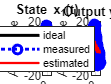


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RESULTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[y_o,t_o,x_o] = lsim( sys, [u 0*w], t);     % IDEAL behavior for comparison
figure(1)
for k = 1:length(sys.A)
    subplot( round((length(sys.A)+1)/2 ),2,k)
    plot(t,x_o(:,k),'k','linewidth',2); hold on;
    plot(t,x_(:,k),'bo:','linewidth',2); 
    stairs(t,x(:,k),'r','linewidth',1.5);
    xlabel('Time (s)'); ylabel('Amplitude'); title(['State x_' num2str(k) '(t)']); grid on;
    legend('ideal','real','estimated'); hold off;
end
subplot( round((length(sys.A)+1)/2 ),2,k+1)
plot(t,y_o,'k','linewidth',2); hold on;
plot(t,z,'bo:','linewidth',2);
stairs(t,y,'r','linewidth',1.5);
xlabel('Time (s)'); ylabel('Amplitude'); title('Output y(t)'); grid on;
legend('ideal','measured','estimated');

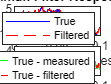


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RESULTS 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%connect to join sys and the Kalman filter together such that u is a shared input and the noisy plant output y feeds into the other filter input.

sys.InputName = {'u','w'};
sys.OutputName = {'yt'};
vIn = sumblk('y=yt+v');
kalmf.InputName = {'u','y'};
kalmf.OutputName = 'ye';
SimModel = connect(sys,vIn,kalmf,{'u','w','v'},{'yt','ye'});

%To simulate the filter behavior, generate a known sinusoidal input vector.
u = sin(t/5);
%Generate process noise and sensor noise vectors using the same noise covariance values Q and R that you used to design the filter.
rng(10,'twister');
w1 = sqrt(Q)*randn(length(t),1);
v1 = sqrt(R)*randn(length(t),1);

%Finally, simulate the response using lsim.
out = lsim(SimModel,[u,w1,v1]);
%lsim generates the response at the outputs yt and ye to the inputs applied at w, v, and u. Extract the yt and ye channels and compute the measured response.

yt = out(:,1);   % true response
ye = out(:,2);  % filtered response
y = yt + v1;     % measured response

%Compare the true response with the filtered response.
clf
subplot(211), plot(t,yt,'b',t,ye,'r--'), 
xlabel('Number of Samples'), ylabel('Output')
title('Kalman Filter Response')
legend('True','Filtered')
subplot(212), plot(t,yt-y,'g',t,yt-ye,'r--'),
xlabel('Number of Samples'), ylabel('Error')
legend('True - measured','True - filtered')


%covariance of the error before filtering (measurement error covariance)
MeasErr = yt-yt;
MeasErrCov = sum(MeasErr.*MeasErr)/length(MeasErr)  %=0

MeasErrCov = 0

% and after filtering (estimation error covariance)
EstErr = yt-ye;
EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

EstErrCov = 0.5254

% so the Kalman filter reduces the error yt - y due to measurement noise

function [ x, y, K_m, P_m ] = kalman_filter( sysd, u, w, z, t, x_0, P_0, R, Q )
% discrete-time model
F = sysd.a;
G = sysd.b(:,1);
H = sysd.c;
J = sysd.b(:,2:end);
% initialization
k = 1 +1;
x = x_0;                 
P = P_0;
I = diag( ones(length(F),1) );
K_m = []; P_m = [];
%%%%%%%%%%%%%%%%%%%%%%%%%%%% kalman filter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n = 1:length(t)-1
    % 1. prediction
    x(:,k) = F*x(:,k-1) +G*u(k-1) +J*w(:,k-1);  % 'a priori' predicted state
    P      = F*P*F' +J*Q*J';                    % 'a priori' predicted covariance
    % 2. correction
    K      = P*H'*inv( H*P*H' +R );             % computes optimal gain   
    e(k)   = z(k) -H*x(:,k);                    % measurement residual
    x(:,k) = x(:,k) +K*e(k);                    % 'a posteriori' state estimative 
    P      = (I -K*H)*P;                        % 'a posteriori' covariance
    
    y(k)   = H*x(:,k);                          % estimated output
    k      = k +1;                              
    
    K_m    = [K_m K];                           % stores current K
    P_m    = [P_m P];                           % stores current P            
end
x = transpose(x);
end


